clc; close all;
k = 4;
d = 30;
n = 5;
m = 1e5;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;

Nruns = 10;
ps = 1;

JPTTime = zeros(ps, Nruns);

CoupledCost1 = zeros(2, Nruns);
CoupledTime1 = zeros(ps, Nruns);

CoupledCost2 = zeros(2, Nruns);
CoupledTime2 = zeros(ps, Nruns);

CoupledCost3 = zeros(2, Nruns);
CoupledTime3 = zeros(ps, Nruns);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);



for j = progress(1:Nruns)

    [T, Os, pi, ~, ~] = generateHMM(k, d, n, hmm_options);
    [seq, ~] = generate_multivariate_hmm_sequence(T, Os, pi, m);
    
    tic
    for ii = 1:n
        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end
    JPTTime(1, j) = toc;




    % Coupled CPD
    tic
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd(P3, k, d, n, 1/(1+alpha), rho, cpd_options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    CoupledCost1(1, j) = norm(T - T_hat, 'fro') / norm(T, 'fro');  
    for ii = 1:n
        CoupledCost1(2, j) = (1/n) * norm(Os{ii} - O_hats{ii}, 'fro') / norm(Os{ii}, 'fro');
    end 
    CoupledTime1(1, j) = toc;





    % Coupled CPD
    tic
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    CoupledCost2(1, j) = norm(T - T_hat, 'fro') / norm(T, 'fro');  
    for ii = 1:n
        CoupledCost2(2, j) = (1/n) * norm(Os{ii} - O_hats{ii}, 'fro') / norm(Os{ii}, 'fro');
    end 
    CoupledTime2(1, j) = toc;




    
    % Coupled CPD
    tic
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_3(P3, k, d, n, alpha, rho, cpd_options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    CoupledCost3(1, j) = norm(T - T_hat, 'fro') / norm(T, 'fro');  
    for ii = 1:n
        CoupledCost3(2, j) = (1/n) * norm(Os{ii} - O_hats{ii}, 'fro') / norm(Os{ii}, 'fro');
    end 
    CoupledTime3(1, j) = toc;
end

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]



% save("PerformanceTests/MethodComparison2", "CoupledCost1", "CoupledTime1", "CoupledCost2", "CoupledTime2", "CoupledCost3", "CoupledTime3",  "JPTTime");



% load("PerformanceTests/MethodComparison2");

[CoupledCost1STDTotal, CoupledCost1MeanTotal] = std(sum(CoupledCost1, 1), 0, 2)
[CoupledCost2STDTotal, CoupledCost2MeanTotal] = std(sum(CoupledCost2, 1), 0, 2)
[CoupledCost3STDTotal, CoupledCost3MeanTotal] = std(sum(CoupledCost3, 1), 0, 2)

[CoupledCost1STD, CoupledCost1Mean] = std(CoupledCost1, 0, 2)
[CoupledCost2STD, CoupledCost2Mean] = std(CoupledCost2, 0, 2)
[CoupledCost3STD, CoupledCost3Mean] = std(CoupledCost3, 0, 2)

[CoupledTime1STD, CoupledTime1Mean] = std(CoupledTime1, 0, 2)
[CoupledTime2STD, CoupledTime2Mean] = std(CoupledTime2, 0, 2)
[CoupledTime3STD, CoupledTime3Mean] = std(CoupledTime3, 0, 2)
[JPTTimeSTD, JPTTimeMean] = std(JPTTime, 0, 2)



figure();

subplot(1, 3, 1)

swarmchart(ones(Nruns, 1), CoupledCost1(1, :)', 'Marker','o'); hold on;
swarmchart(3 *ones(Nruns, 1), CoupledCost2(1, :)', 'Marker','s'); hold on;
swarmchart(5 *ones(Nruns, 1), CoupledCost3(1, :)', 'Marker','^'); hold on;
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F}$", "Interpreter","latex",'FontSize',18,'FontWeight','bold')
% xticklabels(["Baum-Welch","Uncoupled CPD", "Coupled CPD"]) 
set(gca,'YScale','log', 'xtick',[]); grid on;

subplot(1, 3, 2)
swarmchart(ones(Nruns, 1), CoupledCost1(2, :)', 'Marker','o'); hold on;
swarmchart(3 *ones(Nruns, 1), CoupledCost2(2, :)', 'Marker','s'); hold on;
swarmchart(5 *ones(Nruns, 1), CoupledCost3(2, :)', 'Marker','^'); hold on;
ylabel("$\frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',18,'FontWeight','bold')
% xticklabels(["Baum-Welch","Uncoupled CPD", "Coupled CPD"]) 
set(gca,'YScale','log', 'xtick',[]); grid on;

subplot(1, 3, 3)
swarmchart(ones(Nruns, 1), CoupledTime1', 'Marker','o'); hold on;
swarmchart(3 *ones(Nruns, 1), CoupledTime2', 'Marker','s'); hold on;
swarmchart(5 *ones(Nruns, 1), CoupledTime3', 'Marker','^'); hold on;
ylabel("Time [$s$]", "Interpreter","latex",'FontSize',16,'FontWeight','bold')
legend(["Coupled 1","Coupled 2", "Coupled 3"]) 
set(gca,'YScale','log', 'xtick',[]); grid on;





k = 4;
d = 30;
n = 5;
m = 1e6;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 1000;
cpd_options.tol = 1e-20;
cpd_options.th_relerr = 1e-20;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;

[T, Os, pi, ~, ~] = generateHMM(k, d, n, hmm_options);
[seq, ~] = generate_multivariate_hmm_sequence(T, Os, pi, m);

P3 = cell(n, 1);
for ii = 1:n
    P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
end


Acell = cell(n, 1); Bcell = cell(n, 1); Ccell = cell(n, 1);
for ii = 1:n
    Acell{ii} = Stochasticize(ones(d,k) + hmm_options.epsilon * rand(d, k));
    Bcell{ii} = Stochasticize(ones(d,k) + hmm_options.epsilon * rand(d, k));
    Ccell{ii} = Stochasticize(ones(d,k) + hmm_options.epsilon * rand(d, k));
end

init = cell(3, 1);


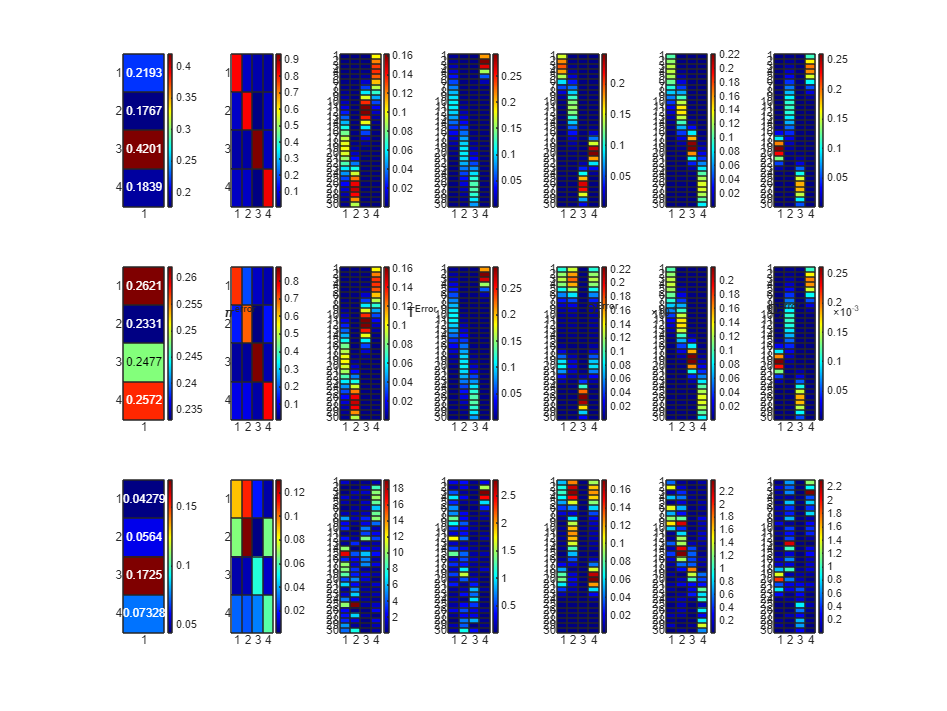

ans = 0.3030

relerror = [];
T_hat = zeros(k, k);
for ii = 1:n
    [A, B, C, ~, output] = cpd_als_3d(P3{ii}, k, cpd_options);
    relerror = [relerror; output.relerr];
    O_hat = Stochasticize(B);
    T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));

    Pbest = PermutationFit(T, T_hats{ii}, true);
    T_hats{ii} = Pbest * T_hats{ii} * Pbest';
    % Pbest * T_hats{ii} * Pbest'
    T_hat = T_hat + (1/n) * T_hats{ii};

    O_hats{ii} = O_hat * Pbest';
end

HMMError(T, Os, T_hat, O_hats, true)

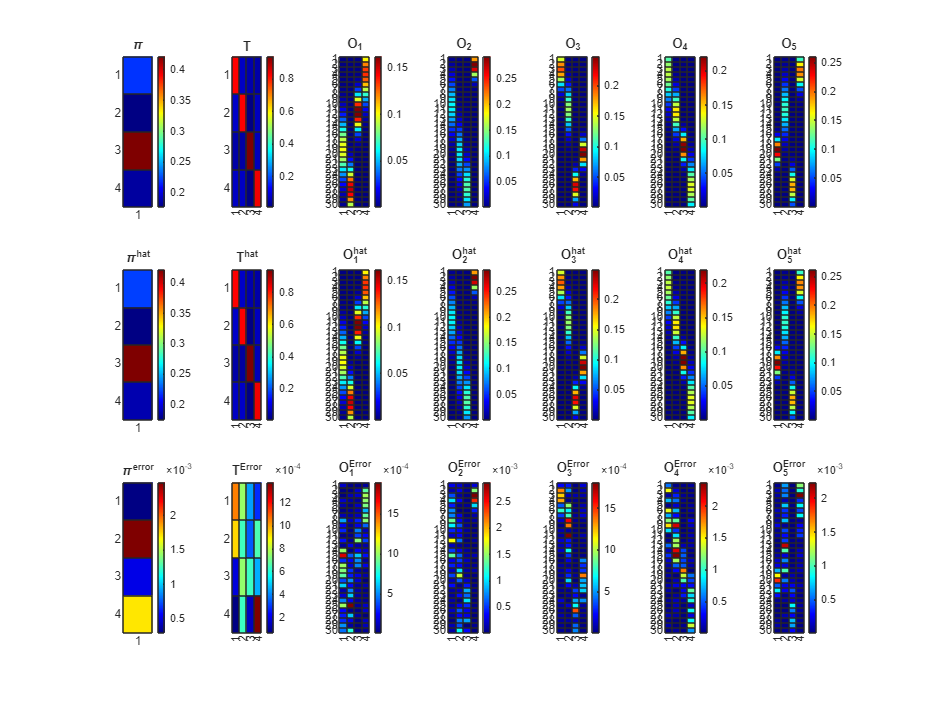

ans = 0.0097



cpd_options.InitialFactor = cell(3, 1);
cpd_options.InitialFactor{1} = Acell; cpd_options.InitialFactor{2} = Bcell; cpd_options.InitialFactor{3} = Ccell;
% Coupled CPD
[T_hat, O_hats, ~, output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
pi_hat = findStationaryDistribution(T_hat')';
[T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

HMMError(T, Os, T_hat, O_hats, true)

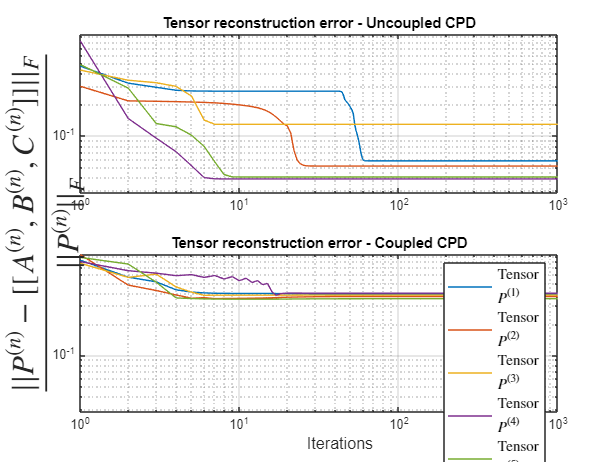


co = cpd_options.maxIter;

fig = figure();
subplot(2,1,1);
loglog(relerror(:, 1:co)');
title('Tensor reconstruction error - Uncoupled CPD');
grid on;
ylim([min([relerror output.rellrecerr], [], 'all')-0.01 max([relerror output.rellrecerr], [], 'all')+0.01]);
xlim([1 co])

subplot(2, 1, 2);
loglog(output.rellrecerr(:, 1:co)')
title("Tensor reconstruction error - Coupled CPD")
legendLabels = arrayfun(@(i) sprintf('Tensor $$ P^{(%d)}$$', i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex', 'FontSize',10);
grid on;
ylim([min([relerror output.rellrecerr], [], 'all')-0.01 max([relerror output.rellrecerr], [], 'all')+0.01]);
xlim([1 co])

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,"$\frac{||P^{(n)} - [[A^{(n)} , B^{(n)} , C^{(n)} ]]||_F}{||P^{(n)}||_F}$", "Interpreter","latex", "FontSize",21, 'FontWeight','bold');
xlabel(han,'Iterations');